## **Modelado de sistemas físicos**

Segunda ley de newton

syms v(t) g cd m 
eqn = diff(v,t) == g -(cd/m)*v^2;
cond = v(0) == 0;
vSym(t) = dsolve(eqn,cond)

$$vSym(t) = \frac{\sqrt{g}\,\sqrt{m}\,\tanh\left(\frac{\sqrt{\mathrm{cd}}\,\sqrt{g}\,t}{\sqrt{m}}\right)}{\sqrt{\mathrm{cd}}}$$

g = 9.81;
m = 68.1;
cd = 0.25;
vel = subs(vSym)

$$vel(t) = \frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,\tanh\left(\frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,t}{13620}\right)}{50}$$

fplot(vel,[0,12]) 
hold on
% tambien se puede hacer como
fin = 12

fin =     12


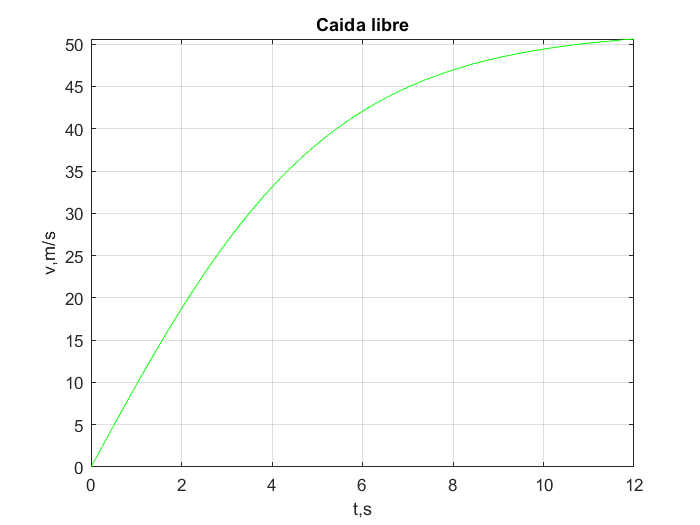

fplot(vel,[0 fin],'g')
hold on
xlabel('t,s')
ylabel('v,m/s')
grid on
title('Caida libre')

### Solución numérica.

*Método de euler*

v'(t) = g -cd/m * v^2

v(0) = 0

size(t)

ans =      1     1


length(t)

ans =      1


v = zeros(1,length(t))

v =      0


Pero es mejor usar la otra notación donde obtenemos las dimensiones del arreglo

v = zeros(size(t));
g = 9.81;
cd = 0.25;
m = 68.1;
h = 1;
t = 0:h:12;
%a = @(v) g-(cd/m)*v^2 %funcion anónima

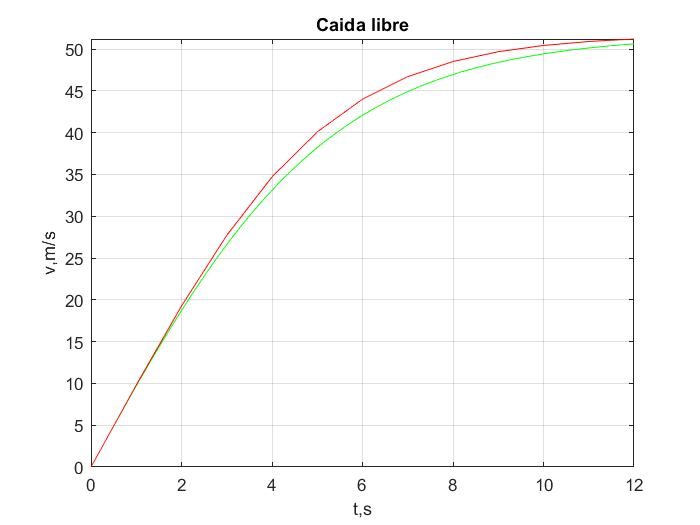

for i=2:length(t)
    v(i) = v(i-1) + caida_libre(g,cd,m,v(i-1));
end

v;
plot(t,v,'r');

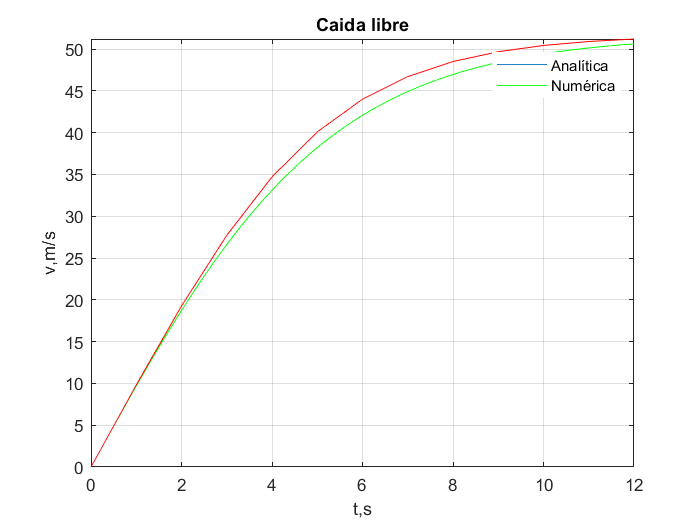

legend('Analítica','Numérica')

% recordemos que x''(t) = a
syms x(t) x0 a v(t) v0;
eqn = diff(x,t,2) == a;
Dx = diff(x,t);
cond = [x(0)==x0, Dx(0)==v0];
xSym(t) = dsolve(eqn,cond) %fisica, sin res del aire

$$xSym(t) = \frac{a\,t^{2}}{2}+v_{0}\,t+x_{0}$$

v(t) = diff(xSym(t),t)

$$v(t) = v_{0}+a\,t$$

eqn = xSym(t) == 0; %dsolve es para eqs diff
tRoot = solve(eqn,t) %todo sigue siendo simbólico porque no les he asignado valores

$$tRoot = \left(\begin{array}{c} -\frac{v_{0}-\sqrt{{v_{0}}^{2}-2\,a\,x_{0}}}{a}\\ -\frac{v_{0}+\sqrt{{v_{0}}^{2}-2\,a\,x_{0}}}{a} \end{array}\right)$$

a = -9.81; %aceleración
x0 = 45; %altura de la quebrada
v0 = 0;
t = double(subs(tRoot)) %convierto a doble y sustituyo/ esto es lo que tarda en caer al mar

t =   -3.028912664076914
   3.028912664076914


v = double(subs(v)) *3600/1000

v = 	1.0e+02 *

   1.069690796445403
  -1.069690796445403
